# Exercise 6: Multiphase flow

## Read data

### Sexy Data Import :)    

sim = readtable("p_rgh");
sim = sim(2:end, :);
sim.Properties.VariableNames

ans = 1×10 cell array
    {'Var1'}    {'Var2'}    {'Var3'}    {'Var4'}    {'Var5'}    {'Var6'}    {'Var7'}    {'Var8'}    {'Var9'}    {'Var10'}



val = readtable("exp_data.txt");

val.Properties.VariableNames

ans = 1×9 cell array
    {'Time_s_'}    {'P1_Pa_'}    {'P2_Pa_'}    {'P3_Pa_'}    {'P4_Pa_'}    {'P5_Pa_'}    {'P6_Pa_'}    {'P7_Pa_'}    {'P8_Pa_'}


## Plot Probe 1

plot(sim.Var1, sim.Var2)
hold on
plot(val.Time_s_, val.P1_Pa_)
hold off

## Plot Probe 1-8

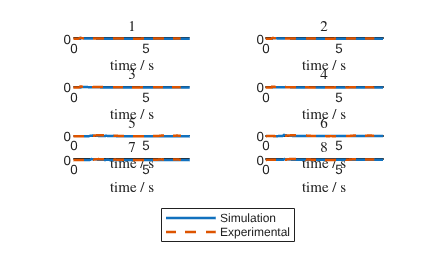

lgd =   Legend (Simulation, Experimental) with properties:

         String: {'Simulation'  'Experimental'}
       Location: 'layout'
    Orientation: 'vertical'
       FontSize: 7.2000
       Position: [0.4220 0.0317 0.1911 0.0786]
          Units: 'normalized'

  Show all properties


tiledlayout(4,2)
for i = 2:9
    nexttile
    col_name_sim = sim.Properties.VariableNames{i};
    col_name_val = val.Properties.VariableNames{i};


    plot(sim.Var1, sim.(col_name_sim), 'LineWidth', 1.5)
    hold on
    plot(val.Time_s_, val.(col_name_val), '--', 'LineWidth', 1.5)
    hold off
    
    title(i-1, 'Interpreter', 'latex')
    xlabel('time / s', 'Interpreter', 'latex')
    ylabel('$p$ / Pa', 'Interpreter', 'latex')
    grid on
end

lgd = legend('Simulation', 'Experimental');
lgd.Layout.Tile= "south"